%% demo_01_cpu_minimal : Minimal smoke test (JSONL/CSV -> optional embeddings -> PCA -> k-means)
% This demo is intentionally minimal.
% - It can run from sample JSONL/CSV alone (no embeddings required).
% - If embeddings are available, it will use them; otherwise it falls back to TF-IDF from text.
clear; clc;

% If topicmap.* isn't visible yet, bootstrap src path once:
% repoRoot = fileparts(fileparts(matlab.desktop.editor.getActiveFilename()));
% addpath(genpath(fullfile(repoRoot,"src"))); rehash;

% Robust repoRoot resolution for Live Script
mlxPath = matlab.desktop.editor.getActiveFilename();
assert(strlength(mlxPath) > 0, "Cannot resolve active file path. Open this .mlx in the Editor and run it.");
examplesDir = fileparts(mlxPath);
repoRoot    = fileparts(examplesDir);
addpath(fullfile(repoRoot,"src"));  % avoid genpath pollution
rehash;

% Bootstrap: define this repo as the OpenAlex hub (session-local)
hubRoot = repoRoot;
setenv("OPENALEX_MATLAB_HUB", hubRoot);

cfg = topicmap.setup("HubRoot", hubRoot);
cfg = topicmap.env_check(cfg);

[topicmap.env_check] WARN (2):
  - Pipeline repo not found (expected <hub>/matlab-openalex-pipeline/src). End-to-end fetch will be unavailable.
  - Normalize repo not found (expected <hub>/matlab-openalex-normalize/src). This is OK for demo_02 (JSONL->map).
[topicmap.env_check] NEXT (4):
  * Clone matlab-openalex-pipeline under hubRoot and re-run topicmap.env_check().
  * For demo_02: set cfg.input.pipelineJsonl to a pipeline output JSONL (works JSONL).
  * Optional: clone matlab-openalex-normalize only if you want CSV-based workflows.
  * Optional: set cfg.sample.worksCsv to support a CSV-based minimal demo (demo_01).


% ---- run output folder ----
cfg.runDir = topicmap.make_run_dir(cfg, "demo01");

plan = topicmap.select_methods(cfg, "PreferUMAP", true, "PreferHDBSCAN", false); % demo_01: no HDBSCAN
disp(plan)

      reducer: "umap"
    clusterer: "kmeans"
     embedder: "bert"
        flags: [1×1 struct]



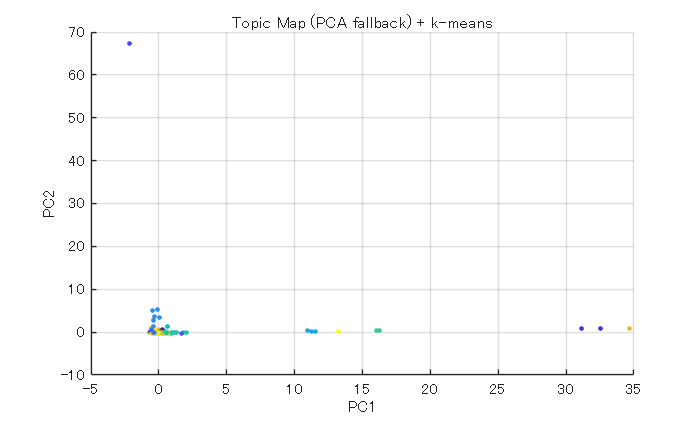


%% Load sample works table (CSV optional, JSONL recommended)
haveCsv   = isfield(cfg,"sample") && isfield(cfg.sample,"worksCsv")   && strlength(string(cfg.sample.worksCsv))>0   && isfile(cfg.sample.worksCsv);
haveJsonl = isfield(cfg,"sample") && isfield(cfg.sample,"worksJsonl") && strlength(string(cfg.sample.worksJsonl))>0 && isfile(cfg.sample.worksJsonl);

assert(haveCsv || haveJsonl, ...
    "No sample input found. Set cfg.sample.worksJsonl (recommended) or cfg.sample.worksCsv.");

if haveJsonl
    W = topicmap.read_pipeline_jsonl(cfg.sample.worksJsonl, "maxRecords", 1000);
    T = struct2table(W);
else
    T = readtable(cfg.sample.worksCsv);
end

% Expect at least an ID column; tolerate different names
idCol = "";
cands = ["work_id","id","openalex_id"];
for c = cands
    if any(strcmpi(T.Properties.VariableNames, c))
        idCol = c; break;
    end
end
assert(strlength(idCol)>0, "worksCsv must include one of these columns: %s", strjoin(cands,", "));

%% Load precomputed embeddings (recommended for demo_01)
haveEmb = isfield(cfg,"sample") && isfield(cfg.sample,"embeddingMat") && ...
          strlength(string(cfg.sample.embeddingMat))>0 && isfile(cfg.sample.embeddingMat);

if haveEmb
    S = load(cfg.sample.embeddingMat);
    assert(isfield(S,"X"), "embeddingMat must contain variable X (n x d).");
    X = S.X;

    % Optional: alignment by IDs if provided
    if isfield(S,"work_id")
        [lia, locb] = ismember(string(T.(idCol)), string(S.work_id));
        if any(~lia)
            warning("Some works rows not found in embeddings; filtering to intersection.");
        end
        T = T(lia,:);
        X = X(locb(lia),:);
    end
else
    % Fallback: build a lightweight TF-IDF matrix from available text fields.
    txt = strings(height(T),1);
    if any(strcmpi(T.Properties.VariableNames,"title"))
        txt = txt + " " + string(T.title);
    end
    if any(strcmpi(T.Properties.VariableNames,"abstract"))
        txt = txt + " " + string(T.abstract);
    end
    if all(strlength(strtrim(txt))==0)
        error("demo01:NoText", "No text fields found (title/abstract). Provide embeddingMat or include text fields.");
    end
    docs = tokenizedDocument(txt);
    bag  = bagOfWords(docs);
    bag  = removeInfrequentWords(bag, 2);
    X    = tfidf(bag);
end

%% Dimensionality reduction
% Default to PCA for demo_01; if you flip plan.reducer later, you can insert UMAP.
rng(cfg.seed);

% pca() does not accept sparse input (e.g., TF-IDF). Convert if needed.
if issparse(X)
    X = full(X);
end

% Reduce to 5D then 2D via PCA (stable + fast)
[~, score5] = pca(X, "NumComponents", 5);
Z5 = score5;

[~, score2] = pca(Z5, "NumComponents", 2);
Z2 = score2;

%% Clustering (k-means)
k = 20;                 % arbitrary demo default; you can tune later
replicates = 5;

labels = kmeans(Z5, k, "Replicates", replicates, "MaxIter", 1000);

%% Plot
fig = figure("Name","OpenAlex Topic Map (PCA fallback)");
scatter(Z2(:,1), Z2(:,2), 8, labels, "filled");
title("Topic Map (PCA fallback) + k-means");
xlabel("PC1"); ylabel("PC2");
grid on;

%% Save outputs into runDir
outPng = fullfile(cfg.runDir, "demo_01_pca_kmeans.png");
saveas(fig, outPng);

fprintf("Saved: %s\n", outPng);

Saved: D:\workspace\github\openalex-topic-map\data_processed\openalex-topicmap\20251223_225936_demo01\demo_01_pca_kmeans.png



% Save minimal manifest for reproducibility
manifest = struct();
manifest.created_at = string(datetime("now"));
manifest.runDir = string(cfg.runDir);
manifest.k = k;
manifest.replicates = replicates;
manifest.seed = cfg.seed;
manifest.n = size(X,1);
manifest.d = size(X,2);
manifest.reducer = "pca(5)->pca(2)";
manifest.clusterer = "kmeans";
manifest.input_mode = ternary(haveEmb, "embeddingMat", "tfidf(title/abstract)");

outJson = fullfile(cfg.runDir, "demo_01_manifest.json");
fid = fopen(outJson, "w");
fwrite(fid, jsonencode(manifest, PrettyPrint=true));
fclose(fid);

function y = ternary(cond, a, b)
    if cond, y = a; else, y = b; end
end
